# Plot (steering & lateral, selfmade)

参数

fontsize = 10;
labels = {'Original System', 'Identified System (cISSIM)', 'Identified System (SID)'};
filepath = 'D:\\OneDrive\\wyqy\\OneDrive\\学习\\!!!NOW!!!\\!!车辆仿真!!\\draft\\fig\\';

时域绘图

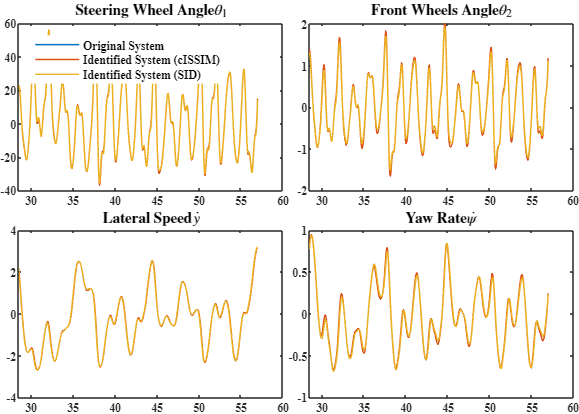

% 切分时间
timerange = fix(0.1*length(ana_t)):fix(0.2*length(ana_t));

% 图窗
f = figure;
f.Units = 'centimeters'; f.Position = [0 0 14 10];

% 布局
tl = tiledlayout(2, 2, 'TileSpacing', 'tight', 'Padding', 'tight');

titleCell = {'\textbf{Steering Wheel Angle} $\theta_1$', '\textbf{Front Wheels Angle} $\theta_2$', ...
    '\textbf{Lateral Speed} $\dot{y}$', '\textbf{Yaw Rate} $\dot{\psi}$'};

for iter = 1:length(titleCell)
    ax = afunc(iter);
    pfunc(t(timerange), rad2deg(ana_ori_yt(timerange, iter)), '#0072BD', '-');
    hold on;
    pfunc(t(timerange), rad2deg(ana_ind_yt(timerange, iter)), '#D95319', '-');
    hold on;
    pfunc(t(timerange), rad2deg(ana_sid_yt(timerange, iter)), '#EDB120', '-');
    title(ax, titleCell{iter}, 'Interpreter', 'latex', ...
        'FontName', 'Times New Roman', 'FontSize', fontsize, 'FontWeight', 'bold');

    if iter == 1, ltimefunc(labels); end
end


% saveas(gcf, [filepath 'steering_lateral_time_domain.eps'], 'epsc')

频域绘图

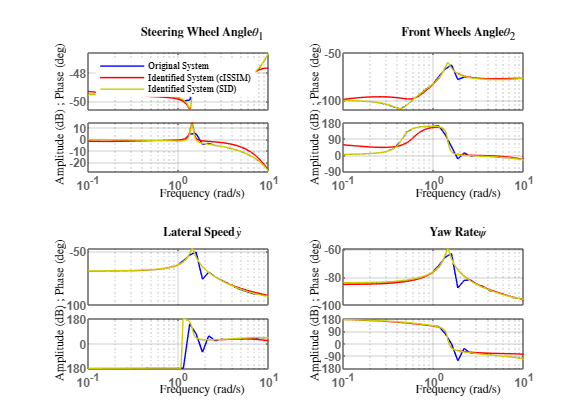

% 图窗
f = figure;
f.Units = 'centimeters'; f.Position = [0 0 14 10];

% subplotwidth = [0.35 0.3]; leftwidth = 0.1; botwidth = 0.5;
% subplotpos = {[leftwidth botwidth subplotwidth], [0 0 subplotwidth], ...
%     [leftwidth+subplotwidth(1) botwidth+subplotwidth(1) subplotwidth], [leftwidth+subplotwidth(1) 0 subplotwidth]};
offCell = {'off', 'off', 'off', 'off'};
titleCell = {'\textbf{Steering Wheel Angle} $\theta_1$', '\textbf{Front Wheels Angle} $\theta_2$', ...
    '\textbf{Lateral Speed} $\dot{y}$', '\textbf{Yaw Rate} $\dot{\psi}$'};

for iter_ax = 1:length(titleCell)
    ax = subplot(2, 2, iter_ax);

    plotoptions = bodeoptions('cstprefs');  % ctrlpref
    plotoptions.PhaseWrapping = 'on';
    plotoptions.IOGrouping = 'all';
    plotoptions.XLabel.String = 'Frequency'; plotoptions.XLabel.FontWeight = 'normal'; plotoptions.XLabel.Interpreter = 'latex';
    plotoptions.YLabel.String = {'Amplitude', 'Phase'}; plotoptions.YLabel.FontWeight = 'normal'; plotoptions.YLabel.Interpreter = 'latex';
    plotoptions.Title.String = titleCell{iter_ax}; plotoptions.Title.Interpreter = 'latex';
    temp = offCell; temp{iter_ax} = 'on'; plotoptions.OutputVisible = temp;
    bodeplot(ax, ana_freq_orifrd, 'b-', ana_freq_indss, 'r-', sid_Model, 'y-', {0.1, 10}, plotoptions);

    if iter_ax == 1, lbodefunc(labels); end
end


% saveas(gcf, [filepath 'steering_lateral_bode_plot.eps'], 'epsc')

函数

function ax = afunc(t)
    ax = nexttile(t);
    % set(gca, 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
end
function pfunc(x, y, color, linestyle)
    plot(x, y, 'Color', color, 'LineStyle', linestyle, 'LineWidth', 1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 8, 'FontWeight', 'bold');
end
function ltimefunc(texts)
    lgd = legend(texts, 'FontName', 'Times New Roman', 'FontSize', 8, 'FontWeight', 'bold');
    lgd.Location = 'northwest'; lgd.Box = 'off';
end
function lbodefunc(texts)
    lgd = legend(texts, 'FontName', 'Times New Roman', 'FontSize', 6, 'FontWeight', 'bold');
    lgd.Location = 'northwest'; lgd.Box = 'off';
end